## Modal Analysis for ME 599

## Bookkeeping

By Connor Getz Created: 04/05/2024 Last Editted: 04/22/2024

## Notes

- All Trig is radian based

## 1. Givens and Inputs

% Givens
clear, clc, close all;
% NOTE: Sea Level US Standard Atmosphere means 15C, ~101.3kPa (abs), 0% Humidity
k = 12000;                    %45.98;              % [N/m] Fluid Stiffness
L = 1.13;     %1.448;              % [m] Length of the Enclosure
rho = 1.225;            % [kg/m^3] Density of air at NC, Dry Air
Area = 0.02483;         % [m^2] Cross-sectional Area of the Enclosure
P_0 = 0.02;             % [m] Driver Offset
x_0 = 0;                % [m] Initial Position
v_0 = 0;                % [m/s] Initial Velocity
F_0 = 1;                % [N] Force Imparted by the Driver
e = 2.71828;            % [-] Euler's Constant
C = 340.3;                % [m/s] Speed of Sound at NC, Dry Air
E = (C^2)*rho;          % [Pa] Bulk Modulus for Air

% Input
n = 30;

## 2. Space Allocation

Ref = zeros(n,1);
C_ortho = zeros(n,n);
Diag = zeros(n,1);
m_n = zeros(n,n);
k_n = zeros(n,n);
m_dn = zeros(n,1);
k_dn = zeros(n,1);
Omega_nn = zeros(n,1);
Zeta_n = zeros(n,1);

## 3. Evaluating the Characteristic Equation

myfun = @(x) x*cot(x) + ((k*L)/(E*Area));
fun = @(x) myfun(x);
Lambda_n(1,1) = fzero(myfun,0.5);
for i = 2:n
    myfun = @(x) x*cot(x) + ((k*L)/(E*Area));
    Lambda_n(i,1) = fzero(myfun,Lambda_n(i-1,1)+(pi+0.04445176009775278838653811*i));
    Lambda_n(i,2) = Lambda_n(i,1)*2/pi; % For reference

Solved for iteratively to best represent the next root. This function becomes unstable after root 35 and considers asymptotes to be roots. This can be seen in Figure 2: Root Value versus Root Number below.

    Ref(i,1) = Lambda_n(i-1,1)+(pi+0.04445176009775278838653811*i);

    Ref(i,2) = Lambda_n(i-1,1)+pi;

The Ref(i,j) matrix holds the alternative solver guesses used to find the zeros to the Characteristic Equation

end

## 4. Proof of Trigonometric Orthogonality/Solving for Mass and Stiffness Matrices

for i = 1:n
    for j = 1:n
        % To match solution functions in proof
        if  i == j
            C_ortho(i,j) = -((L*(sin(2*Lambda_n(i,1))-2*Lambda_n(i,1)))/(4*Lambda_n(i,1)));
            %C_ortho(i,j) = (L*sin((2*Lambda_n(i,1)*P_0)/L) - 2*Lambda_n(i,1)*P_0 - L*sin(2*Lambda_n(i,1)) + 2*Lambda_n(i,1)*L)/(4*Lambda_n(i,1));
        else
            C_ortho(i,j) = 0.5*((L/(Lambda_n(i,1)-Lambda_n(j,1)))*sin(Lambda_n(i,1)-Lambda_n(j,1))- ...
            (L/(Lambda_n(i,1)+Lambda_n(j,1)))*sin(Lambda_n(i,1)+Lambda_n(j,1)));
        end

Lambda_n is the matrix housing all of the possible values for the integral of the two sine functions. As expected the diagonal of the matrix is the only portion of the matrix that is not zero. Due to the root function becoming unstable, this function is likewise not accurate beyond n = 35.

To Eliminate Solver Error

        if  1*10^-12 > C_ortho(i,j)
            C_ortho(i,j) = 0;
        else
            C_ortho(i,j) = C_ortho(i,j);
        end
        % Establishing mass and stiffness matrices
        m_n(i,j) = C_ortho(i,j); % (cos(Lambda_n(i,1))-1);
        k_n(i,j) = (((Lambda_n(i,1)/L)^2)*C_ortho(i,j)*(C^2)); % (cos(Lambda_n(i,1))-1);
        %C_PDE(i,1) = (-L/rho)*(cos((Lambda_n(i,1)*P_0)/L)-cos(Lambda_n(i,1)));
        %C_PDE(i,1) = (-1/rho)*cos((Lambda_n(i,1)*(P_0))/L);
        C_PDE(i,1) = (1/rho);
    end
end
for i = 1:n
    Diag(i,1) = C_ortho(i,i);
    m_dn(i,1) = m_n(i,i);
    k_dn(i,1) = k_n(i,i);
end

## 5. Experimentally Defined Damping


Omega_Experimental = [130, 140, 260, 290, 390, 420, 510, 580, 670, 710, 1, 33.3, 1, 39.1, 1, 44, 1, 51, 1, 57, 1, 63, 1, 68, 1, 74.5, 1, ...
    80, 1, 86, 1, 92, 1, 98, 1, 104, 1, 110, 1, 115, 1, 121, 1, 127, 1, 133, 1, 139, 1, 145, 1, 151, 1, 156, 1, 163, 1, 169, 1, 175]; % Level 1
%                      53, 56, 170, 180, 250, 275, 360, 380, 500, 530, 1, 33.3, 1, 39.1, 1, 44, 1, 51, 1, 57, 1, 63, 1, 68;...% Level 2
%                      51, 55, 167, 180, 240, 265, 370, 405, 500, 535, 1, 33.3, 1, 39.1, 1, 44, 1, 51, 1, 57, 1, 63, 1, 68;...% Level 3
%                      56, 60, 160, 174, 220, 260, 430, 480, 570, 605, 1, 33.3, 1, 39.1, 1, 44, 1, 51, 1, 57, 1, 63, 1, 68;...% Level 4
%                      45, 49, 170, 185, 240, 270, 360, 410, 505, 545, 1, 33.3, 1, 39.1, 1, 44, 1, 51, 1, 57, 1, 63, 1, 68;...% Level 5
%                      62, 67, 170, 185, 290, 320, 450, 500, 590, 630, 1, 33.3, 1, 39.1, 1, 44, 1, 51, 1, 57, 1, 63, 1, 68;...% Level 6
%                      54, 59, 170, 185, 290, 320, 450, 500, 580, 620, 1, 33.3, 1, 39.1, 1, 44, 1, 51, 1, 57, 1, 63, 1, 68;...% Level 7
%                      57, 62, 185, 200, 275, 305, 420, 475, 560, 605, 1, 33.3, 1, 39.1, 1, 44, 1, 51, 1, 57, 1, 63, 1, 68;...% Level 8
%                      57, 62, 170, 186, 285, 318, 430, 485, 570, 612, 1, 33.3, 1, 39.1, 1, 44, 1, 51, 1, 57, 1, 63, 1, 68;...% Level 9
%                      53, 58, 165, 183, 290, 323, 440, 495, 550, 595, 1, 33.3, 1, 39.1, 1, 44, 1, 51, 1, 57, 1, 63, 1, 68;...% Level 10
%                      64, 70, 172, 190, 290, 325, 450, 435, 590, 635, 1, 33.3, 1, 39.1, 1, 44, 1, 51, 1, 57, 1, 63, 1, 68;...% Level 11
%                      50, 57, 160, 180, 295, 330, 440, 495, 580, 625, 1, 33.3, 1, 39.1, 1, 44, 1, 51, 1, 57, 1, 63, 1, 68;...% Level 12
%                      50, 57, 160, 180, 295, 330, 430, 490, 570, 620, 1, 33.3, 1, 39.1, 1, 44, 1, 51, 1, 57, 1, 63, 1, 68;...% Level 13
%                      58, 65, 170, 190, 290, 330, 420, 480, 560, 610, 1, 33.3, 1, 39.1, 1, 44, 1, 51, 1, 57, 1, 63, 1, 68]; % Level 14 - Picked Points from Experiemtnal Real Graph

for i = 1:n
    Omega_nn(i,1) = sqrt(k_n(i,i)/m_n(i,i));
    Omega_nCheck(i,1) = (Lambda_n(i,1)*C)/L; 
    Omega_nHz(i,1) = Omega_nn(i,1)/6.2831853;
end


for i = 1:n
    j = (i-1)*2;
    Zeta_n(i,1) = ((Omega_Experimental(1,j+2)-Omega_Experimental(1,j+1))/(2*Omega_nHz(i,1)));
    c_n = (2*Zeta_n(i,1)*Omega_nn)/m_n(i,i);
end

if Zeta_n(1,1) >= 1 % Should be the largest Zeta value
    disp('Warning: Impossible Zeta')
end

## 6. Establishing the Final EOM

### Establishing ODE Constants

for i = 1:n
    B_ODE(i,1) = (k_n(i,i)/m_n(i,i));
    A_ODE(i,1) = 2*Zeta_n(i,1)*Omega_nn(i,1);
    C_ODE(i,1) = C_PDE(i,1)/m_n(i,i);
end

### Identifying the ODE's Roots

for i = 1:n
    Root_ODE(i,1) = 0.5*(-A_ODE(i,1)+sqrt((A_ODE(i,1)^2)-4*B_ODE(i,1)) );
end

### Following Inmann Textbook Solution

NOTE: 59.2, 177.7, ... are modal Natural Frequencies

k_driver = 0.00071;          % [m/N] Mechanical Compliance of the Driver Suspension (ND140-4 Manual)
S_d = 0.00866;               % [m^2] Surface Area of the Driver
P_ref = 2*10^(-2);           % [Pa] Reference Pressure used for Decibel Calculation (Engineering Toolbox)

for w = 20:20000
    Omega_Hz = w;             % [Hz] Forcing Function Frequency
    Omega = Omega_Hz*6.2831853;    % [Rad/s] Forcing Function Frequency
    %Omega = Omega_nn(1, 1)+0.001;
    
    for i = 1:n
        f_0(i,1) = (F_0*C_ODE(i,1)); % Corrected Force
        A_sol(i,1) = real(Root_ODE(i,1)); % w_d
        B_sol(i,1) = imag(Root_ODE(i,1)); % -Zeta_n*Omega_nn
        Theta_n(i,1) = atan((x_0*A_sol(i,1))/((Omega_nn(i,1)^2)-(Omega^2)));
        X_n(i,1) = (f_0(i,1)/C_ortho(i,i))/sqrt((Omega_nn(i,1)^2-Omega^2)^2 +(2*Zeta_n(i,1)*Omega_nn(i,1)*Omega)^2);
        Phi_n(i,1) = atan((A_sol(i,1)*(x_0-X_n(i,1)*cos(Theta_n(i,1))))/(v_0+(x_0-X_n(i,1)*cos(Theta_n(i,1)))*Zeta_n(i,1)*Omega_nn(i,1)-Omega*X_n(i,1)*sin(Theta_n(i,1))));
        A_n(i,1) = (x_0 - X_n(i,1)*cos(Theta_n(i,1)))/(sin(Phi_n(i,1)));
    end
    t = 0.05:0.00001:0.2;
    Y_n1 = A_n(1,1).*(e.^(-B_sol(1,1).*t)).*sin(A_sol(1,1).*t+Phi_n(1,1))+X_n(1,1).*cos(Omega.*t-Theta_n(1,1));
    Y_n2 = A_n(2,1).*(e.^(-B_sol(2,1).*t)).*sin(A_sol(2,1).*t+Phi_n(2,1))+X_n(2,1).*cos(Omega.*t-Theta_n(2,1));
    Y_n3 = A_n(3,1).*(e.^(-B_sol(3,1).*t)).*sin(A_sol(3,1).*t+Phi_n(3,1))+X_n(3,1).*cos(Omega.*t-Theta_n(3,1));
    Y_n4 = A_n(4,1).*(e.^(-B_sol(4,1).*t)).*sin(A_sol(4,1).*t+Phi_n(4,1))+X_n(4,1).*cos(Omega.*t-Theta_n(4,1));
    Y_n5 = A_n(5,1).*(e.^(-B_sol(5,1).*t)).*sin(A_sol(5,1).*t+Phi_n(5,1))+X_n(5,1).*cos(Omega.*t-Theta_n(5,1));
    Y_n6 = A_n(6,1).*(e.^(-B_sol(6,1).*t)).*sin(A_sol(6,1).*t+Phi_n(6,1))+X_n(6,1).*cos(Omega.*t-Theta_n(6,1));
    Y_n7 = A_n(7,1).*(e.^(-B_sol(7,1).*t)).*sin(A_sol(7,1).*t+Phi_n(7,1))+X_n(7,1).*cos(Omega.*t-Theta_n(7,1));
    Y_n8 = A_n(8,1).*(e.^(-B_sol(8,1).*t)).*sin(A_sol(8,1).*t+Phi_n(8,1))+X_n(8,1).*cos(Omega.*t-Theta_n(8,1));
    Y_n9 = A_n(9,1).*(e.^(-B_sol(9,1).*t)).*sin(A_sol(9,1).*t+Phi_n(9,1))+X_n(9,1).*cos(Omega.*t-Theta_n(9,1));
    Y_n10 = A_n(10,1).*(e.^(-B_sol(10,1).*t)).*sin(A_sol(10,1).*t+Phi_n(10,1))+X_n(10,1).*cos(Omega.*t-Theta_n(10,1));
    Y_n11 = A_n(11,1).*(e.^(-B_sol(11,1).*t)).*sin(A_sol(11,1).*t+Phi_n(11,1))+X_n(11,1).*cos(Omega.*t-Theta_n(11,1));
    Y_n12 = A_n(12,1).*(e.^(-B_sol(12,1).*t)).*sin(A_sol(12,1).*t+Phi_n(12,1))+X_n(12,1).*cos(Omega.*t-Theta_n(12,1));
    Y_n13 = A_n(13,1).*(e.^(-B_sol(13,1).*t)).*sin(A_sol(13,1).*t+Phi_n(13,1))+X_n(13,1).*cos(Omega.*t-Theta_n(13,1));
    Y_n14 = A_n(14,1).*(e.^(-B_sol(14,1).*t)).*sin(A_sol(14,1).*t+Phi_n(14,1))+X_n(14,1).*cos(Omega.*t-Theta_n(14,1));
    Y_n15 = A_n(15,1).*(e.^(-B_sol(15,1).*t)).*sin(A_sol(15,1).*t+Phi_n(15,1))+X_n(15,1).*cos(Omega.*t-Theta_n(15,1));
    Y_n16 = A_n(16,1).*(e.^(-B_sol(16,1).*t)).*sin(A_sol(16,1).*t+Phi_n(16,1))+X_n(16,1).*cos(Omega.*t-Theta_n(16,1));
    Y_n17 = A_n(17,1).*(e.^(-B_sol(17,1).*t)).*sin(A_sol(17,1).*t+Phi_n(17,1))+X_n(17,1).*cos(Omega.*t-Theta_n(17,1));
    Y_n18 = A_n(18,1).*(e.^(-B_sol(18,1).*t)).*sin(A_sol(18,1).*t+Phi_n(18,1))+X_n(18,1).*cos(Omega.*t-Theta_n(18,1));
    Y_n19 = A_n(19,1).*(e.^(-B_sol(19,1).*t)).*sin(A_sol(19,1).*t+Phi_n(19,1))+X_n(19,1).*cos(Omega.*t-Theta_n(19,1));
    Y_n20 = A_n(20,1).*(e.^(-B_sol(20,1).*t)).*sin(A_sol(20,1).*t+Phi_n(20,1))+X_n(20,1).*cos(Omega.*t-Theta_n(20,1));
    Y_n21 = A_n(21,1).*(e.^(-B_sol(21,1).*t)).*sin(A_sol(21,1).*t+Phi_n(21,1))+X_n(21,1).*cos(Omega.*t-Theta_n(21,1));
    Y_n22 = A_n(22,1).*(e.^(-B_sol(22,1).*t)).*sin(A_sol(22,1).*t+Phi_n(22,1))+X_n(22,1).*cos(Omega.*t-Theta_n(22,1));
    Y_n23 = A_n(23,1).*(e.^(-B_sol(23,1).*t)).*sin(A_sol(23,1).*t+Phi_n(23,1))+X_n(23,1).*cos(Omega.*t-Theta_n(23,1));
    Y_n24 = A_n(24,1).*(e.^(-B_sol(24,1).*t)).*sin(A_sol(24,1).*t+Phi_n(24,1))+X_n(24,1).*cos(Omega.*t-Theta_n(24,1));
    Y_n25 = A_n(25,1).*(e.^(-B_sol(25,1).*t)).*sin(A_sol(25,1).*t+Phi_n(25,1))+X_n(25,1).*cos(Omega.*t-Theta_n(25,1));
    Y_n26 = A_n(26,1).*(e.^(-B_sol(26,1).*t)).*sin(A_sol(26,1).*t+Phi_n(26,1))+X_n(26,1).*cos(Omega.*t-Theta_n(26,1));
    Y_n27 = A_n(27,1).*(e.^(-B_sol(27,1).*t)).*sin(A_sol(27,1).*t+Phi_n(27,1))+X_n(27,1).*cos(Omega.*t-Theta_n(27,1));
    Y_n28 = A_n(28,1).*(e.^(-B_sol(28,1).*t)).*sin(A_sol(28,1).*t+Phi_n(28,1))+X_n(28,1).*cos(Omega.*t-Theta_n(28,1));
    Y_n29 = A_n(29,1).*(e.^(-B_sol(29,1).*t)).*sin(A_sol(29,1).*t+Phi_n(29,1))+X_n(29,1).*cos(Omega.*t-Theta_n(29,1));
    Y_n30 = A_n(30,1).*(e.^(-B_sol(30,1).*t)).*sin(A_sol(30,1).*t+Phi_n(30,1))+X_n(30,1).*cos(Omega.*t-Theta_n(30,1));
    Y_total = Y_n1 + Y_n2 + Y_n3 + Y_n4 + Y_n5 + Y_n6 + Y_n7 + Y_n8 + Y_n9 + Y_n10...
        + Y_n11 + Y_n12 + Y_n13 + Y_n14 + Y_n15 + Y_n16 + Y_n17 + Y_n18 + Y_n19 + Y_n20...
        + Y_n21 + Y_n22 + Y_n23 + Y_n24 + Y_n25 + Y_n26 + Y_n27 + Y_n28 + Y_n29 + Y_n30;
    Dis1(w,1) = abs(max(Y_n1));
    Dis2(w,1) = abs(max(Y_n2));
    Dis3(w,1) = abs(max(Y_n3));
    Dis4(w,1) = abs(max(Y_n4));
    Dis5(w,1) = abs(max(Y_n5));
    Dis6(w,1) = abs(max(Y_n6));
    Dis7(w,1) = abs(max(Y_n7));
    Dis8(w,1) = abs(max(Y_n8));
    Dis9(w,1) = abs(max(Y_n9));
    Dis10(w,1) = abs(max(Y_n10));
    Dis11(w,1) = abs(max(Y_n11));
    Dis12(w,1) = abs(max(Y_n12));
    Dis13(w,1) = abs(max(Y_n13));
    Dis14(w,1) = abs(max(Y_n14));
    Dis15(w,1) = abs(max(Y_n15));
    Dis16(w,1) = abs(max(Y_n16));
    Dis17(w,1) = abs(max(Y_n17));
    Dis18(w,1) = abs(max(Y_n18));
    Dis19(w,1) = abs(max(Y_n19));
    Dis20(w,1) = abs(max(Y_n20));
    Dis21(w,1) = abs(max(Y_n21));
    Dis22(w,1) = abs(max(Y_n22));
    Dis23(w,1) = abs(max(Y_n23));
    Dis24(w,1) = abs(max(Y_n24));
    Dis25(w,1) = abs(max(Y_n25));
    Dis26(w,1) = abs(max(Y_n26));
    Dis27(w,1) = abs(max(Y_n27));
    Dis28(w,1) = abs(max(Y_n28));
    Dis29(w,1) = abs(max(Y_n29));
    Dis30(w,1) = abs(max(Y_n30));
    Dis(w,1) = abs(max(Y_total));
    Omega_Tracker(w,1) = w;
    F_Applied = Dis(w,1)/k_driver;                 % [N] Approximated force applied by the driver
%    P_Applied(w,1) = F_Applied/S_d;                     % [Pa] Pressure wave created by the driver
    P_Applied(w,1) = w*E*(abs(((Lambda_n(1,1)/L)*cos(Lambda_n(1,1)))*Dis1(w,1)) + abs(((Lambda_n(2,1)/L)*cos(Lambda_n(2,1)))*Dis2(w,1)) + abs(((Lambda_n(3,1)/L)*cos(Lambda_n(3,1)))*Dis3(w,1)) + abs(((Lambda_n(4,1)/L)*cos(Lambda_n(4,1)))*Dis4(w,1)) ...
        + abs(((Lambda_n(5,1)/L)*cos(Lambda_n(5,1)))*Dis5(w,1))+ abs(((Lambda_n(6,1)/L)*cos(Lambda_n(6,1)))*Dis6(w,1))+ abs(((Lambda_n(7,1)/L)*cos(Lambda_n(7,1)))*Dis7(w,1))+ abs(((Lambda_n(8,1)/L)*cos(Lambda_n(8,1)))*Dis8(w,1))...
        + abs(((Lambda_n(9,1)/L)*cos(Lambda_n(9,1)))*Dis9(w,1))+ abs(((Lambda_n(10,1)/L)*cos(Lambda_n(10,1)))*Dis10(w,1))+ abs(((Lambda_n(11,1)/L)*cos(Lambda_n(11,1)))*Dis11(w,1))+ abs(((Lambda_n(12,1)/L)*cos(Lambda_n(12,1)))*Dis12(w,1))...
        + abs(((Lambda_n(13,1)/L)*cos(Lambda_n(13,1)))*Dis13(w,1))+ abs(((Lambda_n(14,1)/L)*cos(Lambda_n(14,1)))*Dis14(w,1))+ abs(((Lambda_n(15,1)/L)*cos(Lambda_n(15,1)))*Dis15(w,1))+ abs(((Lambda_n(16,1)/L)*cos(Lambda_n(16,1)))*Dis16(w,1))...
        + abs(((Lambda_n(17,1)/L)*cos(Lambda_n(17,1)))*Dis17(w,1))+ abs(((Lambda_n(18,1)/L)*cos(Lambda_n(18,1)))*Dis18(w,1))+ abs(((Lambda_n(19,1)/L)*cos(Lambda_n(19,1)))*Dis19(w,1))+ abs(((Lambda_n(20,1)/L)*cos(Lambda_n(20,1)))*Dis20(w,1))...
        + abs(((Lambda_n(21,1)/L)*cos(Lambda_n(21,1)))*Dis21(w,1))+ abs(((Lambda_n(22,1)/L)*cos(Lambda_n(22,1)))*Dis22(w,1))+ abs(((Lambda_n(23,1)/L)*cos(Lambda_n(23,1)))*Dis23(w,1))+ abs(((Lambda_n(24,1)/L)*cos(Lambda_n(24,1)))*Dis24(w,1))...
        + abs(((Lambda_n(25,1)/L)*cos(Lambda_n(25,1)))*Dis25(w,1))+ abs(((Lambda_n(26,1)/L)*cos(Lambda_n(26,1)))*Dis26(w,1))+ abs(((Lambda_n(27,1)/L)*cos(Lambda_n(27,1)))*Dis27(w,1))+ abs(((Lambda_n(28,1)/L)*cos(Lambda_n(28,1)))*Dis28(w,1))...
        + abs(((Lambda_n(29,1)/L)*cos(Lambda_n(29,1)))*Dis29(w,1))+ abs(((Lambda_n(30,1)/L)*cos(Lambda_n(30,1)))*Dis30(w,1)));

    SPL(w,1) = 10*log10((P_Applied(w,1)^2)/(P_ref^2));    % [dB] Sound Pressure Level created at the driver in decibels

%     if  SPL(w,1) < 0
%         break % Exit loop because of error
%     end
end

Compare to Experimental Response

% Corresponding Frequency
F_all = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','Frequency');
% 0 grams of Damping
T_0 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','S1.000.W.01');
T_0P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.000.W.01');

## Data Visualization

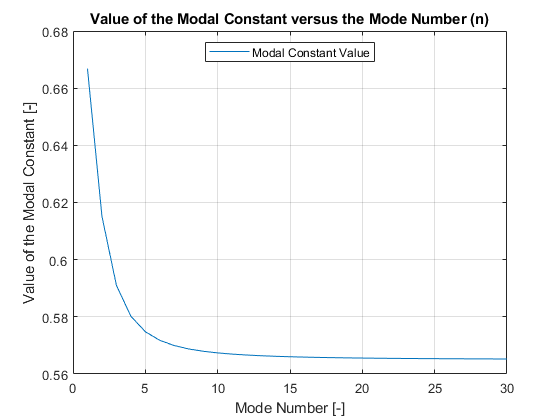

x_testplot = 1:n;
% Figure 1
f1 = figure('Name','Figure 1: Modal Constants','NumberTitle','off');
plot(x_testplot, Diag(:,1))
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
%ylim([100 116]);
%xlim([33 37]);
title('Value of the Modal Constant versus the Mode Number (n)');
ylabel('Value of the Modal Constant [-]');
xlabel('Mode Number [-]');
legend('Modal Constant Value', 'location','N')

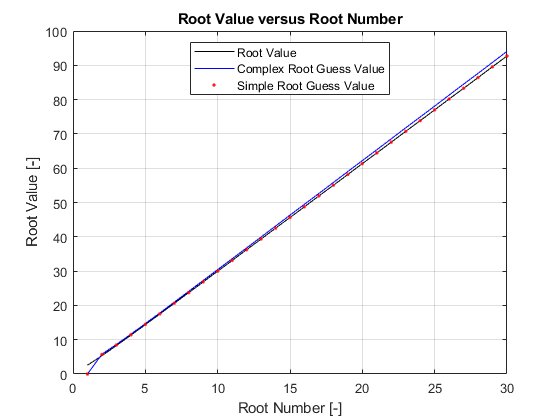

% Figure 2
f2 = figure('Name','Figure 2: Root Value versus Root Number', ...
    'NumberTitle','off');
plot(x_testplot, Lambda_n(:,1), "k", x_testplot, Ref(:,1), "b", ...
    x_testplot, Ref(:,2), ".r")
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
%ylim([100 116]);
%xlim([33 37]);
title('Root Value versus Root Number');
ylabel('Root Value [-]');
xlabel('Root Number [-]');
legend('Root Value','Complex Root Guess Value', ...
    'Simple Root Guess Value','location','N')

Figure 5

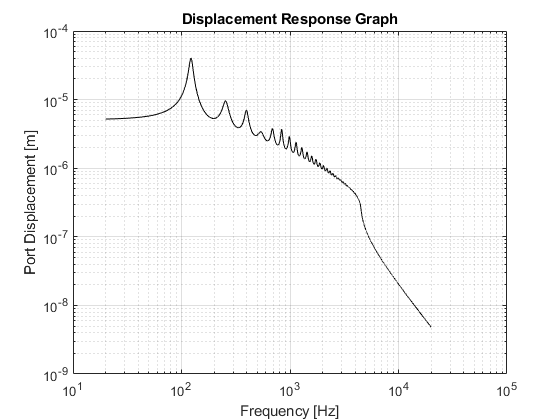

% Figure 5
f5 = figure('Name','Figure 5: Displacement Frequency Response', ...
    'NumberTitle','off');
loglog(Omega_Tracker(:,1), Dis(:,1),'k');
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
%ylim([-1.5 1.5]);
%xlim([0 0.02]);
%Adds title
title('Displacement Response Graph');
xlabel('Frequency [Hz]');
ylabel('Port Displacement [m]');

Figure 6

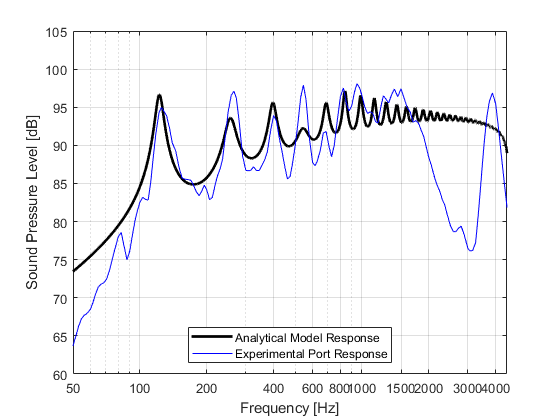

% Figure 6
f6 = figure('Name','Figure 6: Total Frequency Response', ...
    'NumberTitle','off');
semilogx(Omega_Tracker(:,1), SPL(:,1),'k', 'LineWidth', 2);
hold on
semilogx(F_all, T_0P(:,21), 'b');
hold off
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
ylim([60 105]);
xlim([50 4500]);
%Adds title
%title('Total Frequency Response Graph');
xticks([50 100 200 400 600 800 1000 1500 2000 3000 4000 5000])
xticklabels({'50', '100', '200', '400', '600', '800', '1000', '1500', '2000', '3000', '4000', '5000'})
xlabel('Frequency [Hz]');
ylabel('Sound Pressure Level [dB]');
legend('Analytical Model Response', 'Experimental Port Response','location','S')

Figure 7

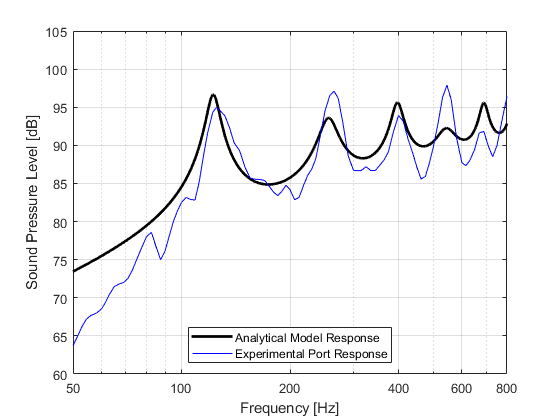

% Figure 7
f7 = figure('Name','Figure 7: Focused Frequency Response', ...
    'NumberTitle','off');
semilogx(Omega_Tracker(:,1), SPL(:,1),'k', 'LineWidth', 2);
hold on
semilogx(F_all, T_0P(:,21), 'b');
hold off
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
ylim([60 105]);
xlim([50 800]);
%Adds title
%title('Total Frequency Response Graph');
xticks([50 100 200 400 600 800])
xticklabels({'50', '100', '200', '400', '600', '800'})
xlabel('Frequency [Hz]');
ylabel('Sound Pressure Level [dB]');
legend('Analytical Model Response', 'Experimental Port Response','location','S')